# Projeto do dia 09/10/2020

João Guilherme Martins Jatobá

18.01790-8

ECM303 - Sistemas de Controle

**Boas práticas**

clear all;
clc;
close all;
% Abrindo dados anteriores para recuperar os ganhos calculados


**Enunciado**

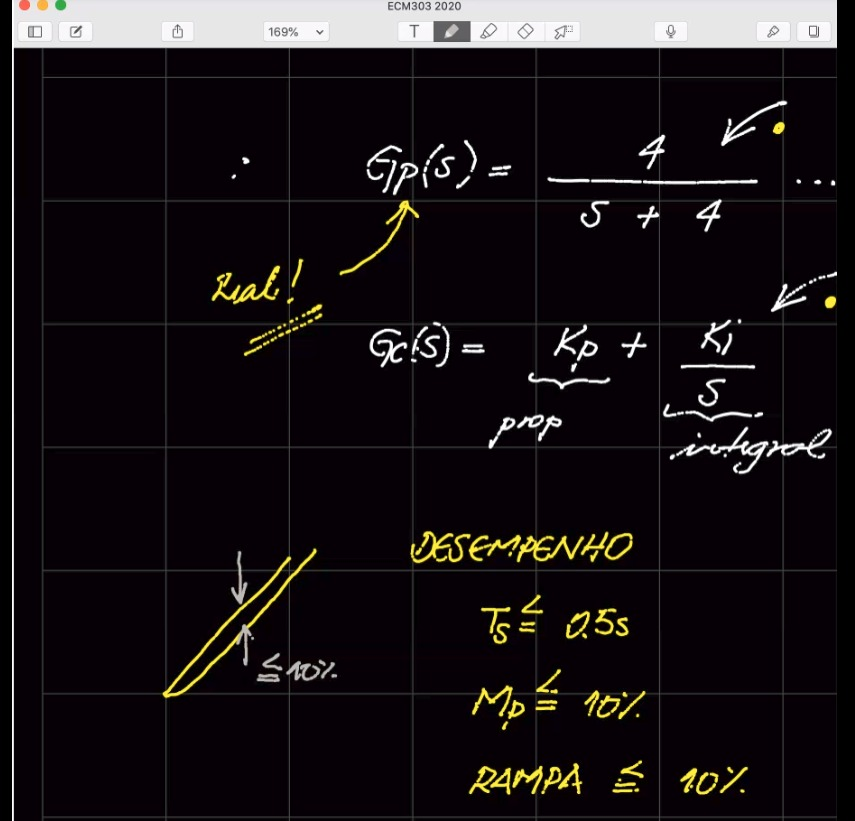

**Teoria do exercício**


$$Gp(s)=\frac{4}{s+4}$$



$$Gc(s)=Kp + \frac{Ki}{s}=\frac{s*Kp + Ki}{s} = \frac{Kp(s+\frac{Ki}{Kp})}{s}$$



$$Zc = \frac{Ki}{Kp}$$



$$Gma(s) = Gp(s)*Gc(s) = \frac{4}{s+4} *  \frac{Kp(s+Zc)}{s}$$



$$Gma(s) = \frac{4Kp(s+Zc)}{s(s+4)}$$



$$Gmf(s) = \frac{Gma(s)}{1+Gma(s)}$$



$$Gmf(s) = \frac{4Kp(s+Zc)}{s(s+4)+4Kp(s+Zc)}=\frac{4Kp(s+Zc)}{s^2+s(4+4Kp)+4KpZc}$$


Forma canônica:


$$\frac{{w_n}^2}{s^2 + 2\zeta w_ns + {w_n}^2}$$
 

A partir dela, chegamos em:

- 
$$2\zeta w_ns = 4+4Kp$$


- 
$${w_n}^2 = 4KpZc=4Ki$$


Encontrando o valor de $\zeta$ a partir de Mp[%]


$$Mp = e^{\frac{-\pi \zeta}{\sqrt{1-\zeta ^2}}}$$



$$\zeta = \sqrt{\frac{ln^2(Mp)}{\pi ^2 + ln^2(Mp)}}$$


Mp = 0.1; % Valor dado no enunciado
zeta = sqrt((log(Mp))^2/(pi^2+(log(Mp))^2));

Encontrando $w_n$ a partir de Ts:


$$Ts(2\%) =  \frac{4}{\zeta w_n}$$



$$w_n = \frac{4}{\zeta Ts}$$


Ts = 0.5; % Valor dado no enunciado
wn = 4/(zeta*Ts);

A partir da equação 1 e dos resultados de $\zeta$ e $w_n$, podemos encontrar Kp:


$$Kp = \frac{2\zeta w_n -4}{4}$$


Kp = (2*zeta*wn-4)/4;

A partir da eq. 2, podemos encontrar Ki:


$$Ki = \frac{{w_n}^2}{4}$$


Ki = wn^2/4;
% Voltando à variável Zc
Zc = Ki/Kp

**Escrevendo os Ganhos:**

Gp = tf([0 0 4],[0 1 4])
Gc = tf([0 Kp Ki],[0 1 0])

Gma = Gp * Gc
Gmf = feedback(Gma,1)
% Gráfico de resposta ao degrau
step(Gmf)
% Informações de resposta ao degrau
stepinfo(Gmf)

% Criando resposta à rampa
time = linspace(0,2,1000);
ramp = time;
y = lsim(Gmf,ramp,time);

figure
plot(time,ramp)
hold
plot(time,y)
grid minor

figure
plot(1-y./ramp')

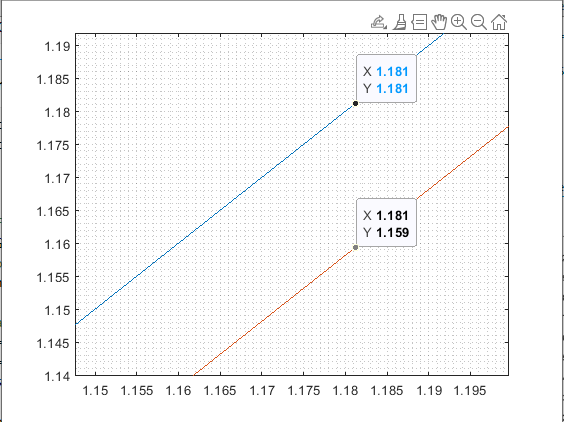

% Dei zoom na resposta à rampa, e fazendo pela diferença, chegamos em:
e = (1.181-1.159)*100/1.181
% Erro ~ 1,86%

% De um jeito que eu pensei que poderia ser
figure
x = lsim(tf(1),ramp,time);
erro=x-y;
plot(time, erro)
title("Erro à rampa")
xlabel("Tempo")
ylabel("Erro[%] /100")